# El atractor de Lorenz: un estudio del caos determinista y el espectro de Lyapunov mediante el método de Benettin

**Modelado y simulación con MATLAB/Simulink R2024a**

### Resumen

El atractor de Lorenz (1963) es uno de los ejemplos canónicos de caos determinista. Este trabajo construye un modelo Simulink del sistema con parámetros σ=10, ρ=28 y β=8/3, en régimen caótico, y analiza su sensibilidad a las condiciones iniciales comparando dos trayectorias que difieren en 10⁻⁶. La divergencia exponencial se cuantifica con el exponente de Lyapunov máximo ($\lambda_1$), estimado por el método de Benettin ($\lambda_1$≈0.907). Se determinan además los exponentes $\lambda_2 \;y\;\lambda_3$ que complementan aspectos clave de la naturaleza caotica y extraña del atractor de Lorenz. Se discute el papel del experimento nominal frente al perturbado.

**Palabras clave:** caos determinista, atractor de Lorenz, exponentes de Lyapunov, método de Benettin, Simulink.

## 1. Introducción

En 1963, Edward Lorenz mostró que un sistema determinista de tres ecuaciones diferenciales exhibe evolución no periódica y dependencia sensible de las condiciones iniciales: dos estados próximos acaban en trayectorias macroscópicamente distintas [1]. Este hallazgo fundó la teoría del caos y dio nombre al **efecto mariposa**. En el presente trabajo se reproduce el sistema de Lorenz en Simulink con dos condiciones iniciales muy cercanas (${10}^{-6}$ y se cuantifica su divergencia mediante la determinación de los exponentes de Lyapunov.

## 2. Objetivos

- Construir un modelo Simulink del sistema de Lorenz con integración RK4 de paso fijo.

- Analizar la sensibilidad a las condiciones iniciales comparando el caso nominal con el perturbado (x₀=1 frente a 1+10⁻⁶).

- Estimar los exponentes de Lyapunov mediante el método de Benettin.

- Relacionar los resultados con la teoría del caos determinista.

## 3. Fundamentación matemática

### 3.1 El modelo de Lorenz

El modelo describe la convección de una capa de fluido mediante el sistema autónomo:


$$\frac{dx}{dt} = \sigma (y - x)$$



$$\frac{dy}{dt} = x (\rho - z) - y$$



$$\frac{dz}{dt} = x y - \beta z$$


Las variables *x, y* y *z *representan la intensidad del movimiento convectivo, la diferencia de temperatura entre corrientes ascendente y descendente y la desviación del perfil térmico vertical. Los parámetros σ (Prandtl), ρ (Rayleigh reducido) y β (razón de aspecto) valen σ=10, ρ=28 y β=8/3, que sitúan el sistema en **régimen caótico.**

### 3.2 El atractor extraño

Se dice que el atractor de Lorenz es "extraño" debido a que su dinámica no converge a un punto fijo ni a un ciclo límite, sino a un conjunto acotado, aperiodico y de dimensión fractal (≈2.06). Las trayectorias sobre él nunca se cierran exactamente pero permanecen acotadas, dando lugar a la estructura en dos alas de la **figura 2**.

### 3.3 Caos determinista

Se dice que el atractor de Lorenz es un sistema determinista, ya que, fijada la condición inicial, la evolución es única y reproducible. Se habla de caos determinista cuando la dinámica es aperiodica y depende sensiblemente de las condiciones iniciales: trayectorias cercanas se separan exponencialmente, aunque el atractor las mantiene acotadas. Por ello, su predicción a largo plazo es en la práctica imposible incluso con modelos exactos.

### 3.4 El exponente de Lyapunov Máximo ($\left.\lambda_1 \right)$

El exponente de Lyapunov máximo λ cuantifica la tasa media de separación entre trayectorias próximas. Si d(t) es la distancia entre dos órbitas, para tiempos cortos se cumple:


$$d(t) = d(0) \, e^{\lambda_{1} t}$$


de modo que $\lambda_1$puede definirse como


$$\lambda_{1} = \frac{1}{t} \ln \left( \frac{d(t)}{d(0)} \right), \quad t \to \infty$$


Un valor $\lambda_1$> 0 indica divergencia exponencial y, con la aperiodicidad, confirma el régimen caótico. Aquí $\lambda_1$ se calcula de forma analítica con las ecuaciones variacionales del flujo, la linealización del sistema: si $\delta$ es una perturbación infinitesimal, su evolución queda gobernada por la matriz jacobiana J(x),


$$\begin{array}{l} \frac{d\delta_x}{dt} = -\sigma\,\delta_x + \sigma\,\delta_y \\ \frac{d\delta_y}{dt} = (\rho - z)\,\delta_x - \delta_y - x\,\delta_z \\ \frac{d\delta_z}{dt} = y\,\delta_x + x\,\delta_y - \beta\,\delta_z \end{array}$$


Junto con las tres ecuaciones originales forma el sistema aumentado de seis ecuaciones que se integra numéricamente.

### 3.5 El método de Benettin

El método de Benettin integra el sistema aumentado sobre intervalos de tiempo Δt y renormaliza el vector de perturbación δ a norma unidad al final de cada intervalo, evitando su saturación sobre el atractor. Tras descartar un transitorio inicial, el exponente se estima como la media


$$\lambda \approx \frac{1}{N \Delta t} \sum_{k=1}^{N} \ln \| \delta_k \|$$


Se integró con **ode45**, Δt=0.5, horizonte t=500 y δ₀=(1,0,0). Se prefirió Benettin a la comparación directa de dos trayectorias por su robustez frente a la saturación del atractor y a la dirección inicial de la perturbación.

function lambda = lorenz_lyapunov_spectrum()
%LORENZ_LYAPUNOV_SPECTRUM  Full Lyapunov spectrum of the Lorenz (1963) system.
%   lambda = lorenz_lyapunov_spectrum()
%
%   Returns the three Lyapunov exponents of the Lorenz system
%       dx/dt = sigma*(y - x)
%       dy/dt = x*(rho - z) - y
%       dz/dt = x*y - beta*z
%   as a 3x1 vector [lambda_1; lambda_2; lambda_3] with lambda_1 >= lambda_2 >=
%   lambda_3. The parameters sigma, rho, beta are read from the base workspace
%   and fall back to the chaotic-regime defaults sigma=10, rho=28, beta=8/3.
%
%   Method (Benettin et al., Gram-Schmidt variant): the 3x3 variational system
%   dQ/dt = J(x)*Q is integrated alongside the orbit, i.e. a 12-state coupled
%   ODE. After every window of dT seconds the tangent basis Q is reorthonormalized
%   by Gram-Schmidt; the log of each column norm, divided by dT, is one sample of
%   the corresponding exponent. The first 25% of the samples (transient needed for
%   the basis to align with the expanding directions) is discarded before averaging.
%
%   Accuracy check: sum(lambda) must equal trace(J) = -(sigma + 1 + beta)
%   (the contraction rate of phase-space volume).

% --- parameters from the base workspace (chaotic regime defaults) ---
try
    sigma = evalin('base', 'sigma'); rho = evalin('base', 'rho'); beta = evalin('base', 'beta');
catch
    sigma = 10; rho = 28; beta = 8/3;
end

% --- Lorenz vector field (states 1:3) ---
fLorenz = @(x) [sigma*(x(2)-x(1)); ...
                x(1)*(rho-x(3))-x(2); ...
                x(1)*x(2)-beta*x(3)];

% --- Jacobian of the vector field, evaluated along the orbit ---
J = @(x) [-sigma, sigma, 0; ...
          rho-x(3), -1, -x(1); ...
          x(2), x(1), -beta];

% --- augmented system: orbit + tangent basis (Q stored as 9 states) ---
fBen = @(t, y) [fLorenz(y(1:3)); ...
                reshape(J(y(1:3))*reshape(y(4:12), 3, 3), 9, 1)];

% tight tolerances: the variational equations are linear and their growth must
% be resolved accurately over a long (500 s) horizon
opts = odeset('AbsTol', 1e-10, 'RelTol', 1e-11);

% --- integration parameters ---
x0  = 1.0; y0 = 1.0; z0 = 1.0;   % initial condition (same as the nominal run)
Q0  = eye(3);                    % orthonormal tangent basis (unit columns)
dT  = 0.5;                       % reorthonormalization window (s)
Tben = 500;                      % total integration horizon (s); long enough for
                                 % lambda_1 to converge (see AGENTS.md check)

% --- Benettin loop: integrate window-by-window, reorthonormalize each dT ---
nWin   = ceil(Tben/dT);           % total number of windows
lamB   = zeros(3, nWin);          % per-window log-growth samples (3 x nWin)
state  = [x0; y0; z0];
Q      = Q0;
tB     = 0;
iw     = 0;
while tB < Tben
    Y = ode45(fBen, [tB tB+dT], [state; Q(:)], opts);
    s = Y.y(:, end);
    state = s(1:3);              % continue the orbit
    V = reshape(s(4:12), 3, 3);  % evolved tangent basis (columns)
    iw = iw + 1;

    % Gram-Schmidt orthonormalization, recording each column's growth
    for k = 1:3
        r = norm(V(:, k));
        if ~(r > 0) || ~isfinite(r)
            error('lorenz_lyapunov_spectrum:nonfinite', ...
                'Tangent norm is not positive and finite at t = %.1f s.', tB);
        end
        lamB(k, iw) = log(r)/dT;
        V(:, k) = V(:, k)/r;                     % normalize q_k
        for j = (k+1):3                          % remove q_k from the rest
            V(:, j) = V(:, j) - (V(:, j).'*V(:, k))*V(:, k);
        end
    end
    Q = V;                       % reorthonormalized basis for the next window
    tB = tB + dT;
end

% --- discard the initial transient, then average the remaining samples ---
k = round(0.25*nWin);
lambda = mean(lamB(:, (k+1):nWin), 2);

end

### 3.6 Importancia del estudio nominal frente al perturbado

Comparar el caso nominal con el perturbado materializa el efecto mariposa: una perturbación de 10⁻⁶ en x₀ produce, tras unos 20–25 s, trayectorias macroscópicamente distintas. El experimento permite calibrar λ con la pendiente de la divergencia en escala logarítmica e ilustra el límite de predictibilidad de los sistemas caóticos, concepto central en meteorología.

## 4. Materiales y métodos

El sistema (1) se implementó en un modelo Simulink (**lorenz_sim**) con tres integradores, sumadores, ganancias y productos, solver de paso fijo ode4 (Runge–Kutta de cuarto orden, Δt=10⁻³) y tiempo de parada de 100 s. Las señales se registran con bloques To Workspace y las condiciones iniciales se leen de x₀, y₀, z₀. El script **simulate_lorenz_chaos** ejecuta las dos simulaciones, remuestrea las trayectorias sobre una malla común de 5000 puntos, calcula la distancia d(t) y estima λ por Benettin. La figura 1 muestra el diagrama de bloques.

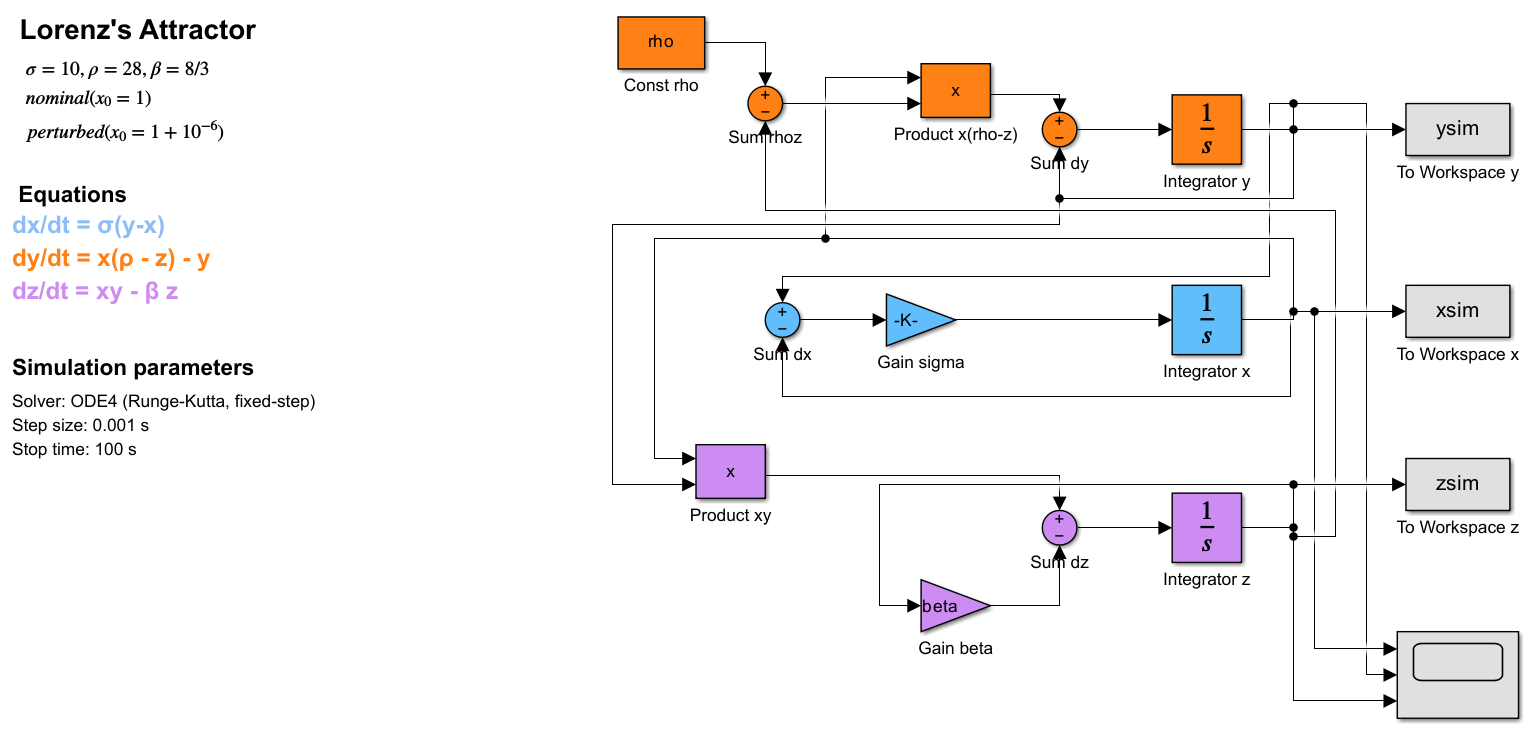

Figura 1. Modelo Simulink  del sistema de Lorenz (σ=10, ρ=28, β=8/3).

## 5. Resultados

La simulación reproduce el atractor y su sensibilidad a las condiciones iniciales: la distancia inicial es d(0)=1.000×10⁻⁶ y tras 40s alcanza d≈9.34, casi siete órdenes de magnitud. El exponente de Benettin es $\lambda_1$≈0.904, en acuerdo con el valor de referencia. La figura 2 presenta el atractor 3D, el retrato de fase x–z y la divergencia en escala logarítmica, con las fases de incubación, crecimiento exponencial y saturación; la recta discontinua es la tasa $\lambda_1$.

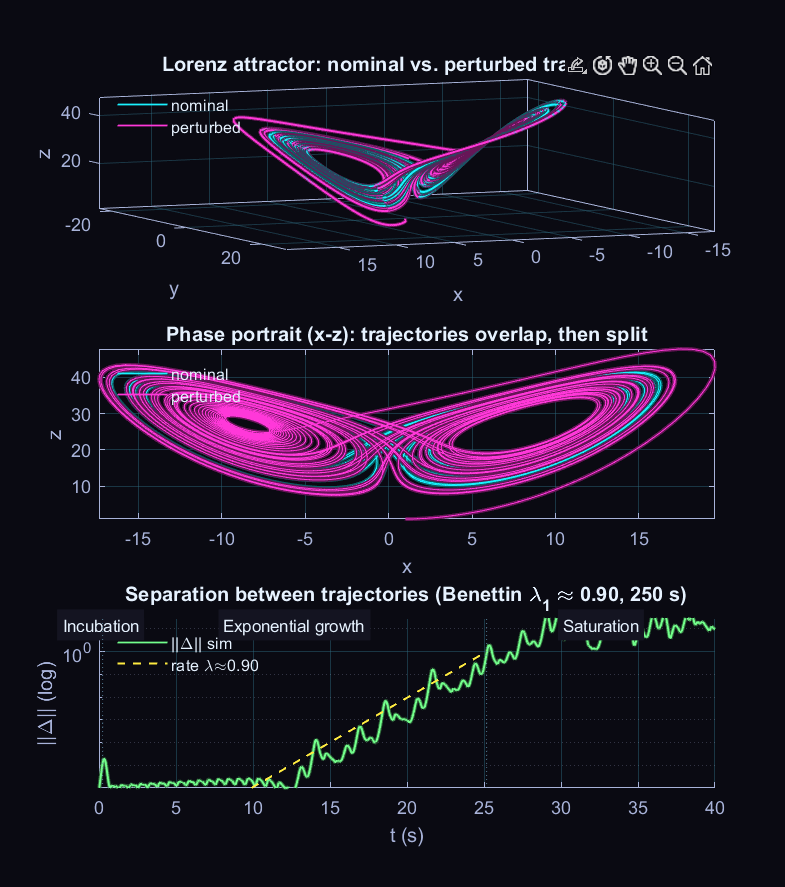

Figura 2. Atractor 3D con las trayectorias nominal y perturbada, espacio de fase en plano x–z y separación ‖Δ‖(t) en escala logarítmica con su pendiente λ≈0.90.

## 6. Conclusiones

El modelo Simulink del sistema de Lorenz reproduce el régimen caótico: el exponente positivo ($\lambda_1$≈0.904) confirma la dependencia sensible de las condiciones iniciales, y el experimento nominal frente al perturbado demuestra el efecto mariposa. El método de Benettin, con ecuaciones variacionales y renormalización periódica, da una estimación robusta de λ. El trabajo muestra el valor pedagógico y científico de Simulink para el estudio de sistemas dinámicos no lineales.

## Referencias

- Lorenz, E. N. Deterministic Nonperiodic Flow. Journal of the Atmospheric Sciences, 20(2), 130–141 (1963). https://doi.org/10.1175/1520-0469(1963)020<0130:DNF>2.0.CO;2

- Strogatz, S. H. Nonlinear Dynamics and Chaos: With Applications to Physics, Biology, Chemistry, and Engineering. 2nd ed., Westview Press (2015).

- Benettin, G., Galgani, L., Giorgilli, A., Strelcyn, J.-M. Lyapunov Characteristic Exponents for Smooth Dynamical Systems and for Hamiltonian Systems: A Method for Computing All of Them. Meccanica, 15(1), 9–20 (1980). https://doi.org/10.1007/BF02128236

- Wolf, A., Swift, J. B., Swinney, H. L., Vastano, J. A. Determining Lyapunov Exponents from a Time Series. Physica D, 16(3), 285–317 (1985). https://doi.org/10.1016/0167-2789(85)90011-9

- Sprott, J. C. Chaos and Time-Series Analysis. Oxford University Press (2003).

- Ott, E. Chaos in Dynamical Systems. 2nd ed., Cambridge University Press (2002).

## Apéndice

### Simulación de Lorenz para Condición nominal y perturbada

% SIMULATE_LORENZ_CHAOS
% Runs the lorenz_sim Simulink model twice: nominal and a tiny perturbed
% initial condition, then animates the deterministic chaos (butterfly effect):
%   subplot 1 -> 3D attractor (nominal vs perturbed)
%   subplot 2 -> phase portrait (x-z projection) to see the trajectories split
%   subplot 3 -> ||Delta||(t) on log scale (exponential divergence)
% Requires lorenz_sim.slx in the same directory

if ~exist('lorenz_sim.slx', 'file')
    build_lorenz_sim();
end
mdl = 'lorenz_sim';

if ~bdIsLoaded(mdl) 
    load_system(mdl)
end

delta = 1e-6;   % tiny perturbation applied to x0
Tend  = 40;

% Ask whether to record the animation as an MP4 (e.g. for an Instagram reel).
% Default is NO, keeping the on-screen animation unchanged. The answer can be
% pre-answered headlessly through the base-workspace variable lorenz_rec_ask
% ('y'/'n'), which avoids blocking in automated/MCP runs.

if evalin('base', 'exist(''lorenz_rec_ask'', ''var'') && ~isempty(lorenz_rec_ask)')
    recChoice = lower(evalin('base', 'lorenz_rec_ask'));
else
    recChoice = lower(strtrim(input('Record animation as Video (MP4 format)? [y/N]: ', 's')));
end
doRecord = ~isempty(recChoice) && recChoice(1) == 'y';
if doRecord
    recFile = 'lorenz_chaos_reel.mp4';
    fprintf('Recording animation to %s (1080x1920, 30 fps, ~12 s) ...\n', recFile);
end

fprintf('Simulating: nominal (x0=1) and perturbed (x0=1+%g) ...\n', delta);
% NOTE: setVariable/setModelParameter on Simulink.SimulationInput silently fail
% in this setup, so we set the base-workspace variables the model reads and the
% model StopTime directly via set_param.
prevStopFcn = get_param(mdl, 'StopFcn');
if isempty(prevStopFcn), prevStopFcn = 'plot_lorenz_attractor'; end   % never leave it blank
set_param(mdl, 'StopFcn', '');
set_param(mdl, 'StopTime', num2str(Tend));   % run only Tend seconds

assignin('base', 'x0', 1.0); assignin('base', 'y0', 1.0); assignin('base', 'z0', 1.0);
sim(mdl);   % nominal run   -> xsim/ysim/zsim in base
t1 = xsim.Time; x1 = xsim.Data; y1 = ysim.Data; z1 = zsim.Data;

assignin('base', 'x0', 1.0 + delta);   % tiny perturbation on x0
sim(mdl);   % perturbed run -> overwrites xsim/ysim/zsim in base
t2 = xsim.Time; x2 = xsim.Data; y2 = ysim.Data; z2 = zsim.Data;

% restore base workspace + model settings used by standalone runs
assignin('base', 'x0', 1.0);
set_param(mdl, 'StopTime', '100');          % restore full stop time
set_param(mdl, 'StopFcn', prevStopFcn);   % restore for standalone model runs

% both runs produce different solver time grids -> resample onto a common grid
tq = linspace(0, Tend, 5000)';
x1 = interp1(t1, x1, tq); y1 = interp1(t1, y1, tq); z1 = interp1(t1, z1, tq);
x2 = interp1(t2, x2, tq); y2 = interp1(t2, y2, tq); z2 = interp1(t2, z2, tq);
t1 = tq;

d = sqrt((x1-x2).^2 + (y1-y2).^2 + (z1-z2).^2);

% Full Lyapunov spectrum via the Benettin method with Gram-Schmidt
% reorthonormalization of the tangent basis: [lambda_1; lambda_2; lambda_3].
% The method integrates the variational equations along a single orbit for
% 250 s (with tight tolerances), so it is robust against attractor saturation
% and does not depend on a single pair of trajectories.
lambda = lorenz_lyapunov_spectrum();
bar = '+---------------------------------------------+';
fprintf('%s\n', bar);
fprintf('| %-26s | %14s |\n', 'Quantity', 'Value');
fprintf('%s\n', bar);
fprintf('| %-26s | %14.3e |\n', 'Initial distance', d(1));
fprintf('| %-26s | %14.3f |\n', 'Final distance', d(end));
fprintf('| %-26s | %14.3f |\n', 'lambda_1 (Benettin)', lambda(1));
fprintf('| %-26s | %14.3f |\n', 'lambda_2 (Benettin)', lambda(2));
fprintf('| %-26s | %14.3f |\n', 'lambda_3 (Benettin)', lambda(3));
fprintf('| %-26s | %14.3f |\n', 'sum lambda (trace check)', sum(lambda));
fprintf('%s\n', bar);

% --- clean exponential-phase window (after incubation, before saturation)
iA = find(d > 1e-5, 1, 'first');
iB = find(d > 0.8, 1, 'first');
if isempty(iA), iA = 1; end
if isempty(iB), iB = numel(d); end
tA = t1(iA); tB = t1(iB);

X = [x1; x2]; Y = [y1; y2]; Z = [z1; z2];

n = numel(t1);
if doRecord
    nFrames = 360;   % 12 s at 30 fps
else
    nFrames = 180;   % as before
end
idx = round(linspace(1, n, nFrames));

close all;   % release figures left open by previous runs
if doRecord
    % 9:16 portrait that fits on the 1536x864 screen; exportgraphics renders
    % it at 1080x1920 regardless of the on-screen size.
    fig = figure('Name', 'Lorenz deterministic chaos', 'Color', [0.04 0.04 0.07], ...
        'Position', [60 40 450 800]);
else
    fig = figure('Name', 'Lorenz deterministic chaos', 'Color', [0.04 0.04 0.07], ...
        'Position', [200 50 820 920]);
end

cNom = [0.10 0.95 1.00];   % neon cyan    (nominal)
cPer = [1.00 0.22 0.85];   % neon magenta  (perturbed)
cSep = [0.45 1.00 0.55];   % neon green    (separation)
cRef = [1.00 0.92 0.25];   % neon yellow   (reference)
cAx  = [0.66 0.70 0.85];   % axis / label ink
cGrid= [0.18 0.42 0.50];   % faint grid
cBg  = [0.04 0.04 0.07];   % panel background
cInk = [0.90 0.95 1.00];   % title / text ink

% --- subplot 1: 3D attractor (cyberpunk dark theme) ---
ax1 = subplot(3,1,1); hold on; grid on; box on; az0 = -27; el0 = 22; view(ax1, az0, el0);
h1g = animatedline('Color', cNom*0.4, 'LineWidth', 2.5);   % subtle neon halo
h1  = animatedline('Color', cNom, 'LineWidth', 1.1);          % bright core
h2g = animatedline('Color', cPer*0.4, 'LineWidth', 2.5);
h2  = animatedline('Color', cPer, 'LineWidth', 1.1);
xlim([min(X) max(X)]); ylim([min(Y) max(Y)]); zlim([min(Z) max(Z)]);
xlabel('x', 'Color', cAx); ylabel('y', 'Color', cAx); zlabel('z', 'Color', cAx);
title('Lorenz attractor: nominal vs. perturbed trajectories', 'Color', cInk);
legend([h1 h2], {'nominal', 'perturbed'}, 'Location', 'northwest', 'Box', 'off', ...
       'TextColor', cInk, 'Color', [0.06 0.06 0.10]);
set(ax1, 'Color', cBg, 'XColor', cAx, 'YColor', cAx, 'ZColor', cAx, ...
         'GridColor', cGrid, 'GridAlpha', 0.45, 'FontSize', 11, ...
         'TitleFontSizeMultiplier', 1.1);

% --- subplot 2: phase portrait (x-z projection) ---
ax2 = subplot(3,1,2); hold on; grid on; box on;
h3g = animatedline('Color', cNom*0.4, 'LineWidth', 2.5);
h3  = animatedline('Color', cNom, 'LineWidth', 1.0);
h4g = animatedline('Color', cPer*0.4, 'LineWidth', 2.5);
h4  = animatedline('Color', cPer, 'LineWidth', 1.0);
xlim([min([x1;x2]) max([x1;x2])]); ylim([min([z1;z2]) max([z1;z2])]);
xlabel('x', 'Color', cAx); ylabel('z', 'Color', cAx);
title('Phase portrait (x-z): trajectories overlap, then split', 'Color', cInk);
legend([h3 h4], {'nominal', 'perturbed'}, 'Location', 'northwest', 'Box', 'off', ...
       'TextColor', cInk, 'Color', [0.06 0.06 0.10]);
set(ax2, 'Color', cBg, 'XColor', cAx, 'YColor', cAx, ...
         'GridColor', cGrid, 'GridAlpha', 0.45, 'FontSize', 11, ...
         'TitleFontSizeMultiplier', 1.1);

% --- subplot 3: separation (log) - dark theme; keeps log scale + reference + regions ---
ax3 = subplot(3,1,3);
hold on;
hdg = animatedline('Color', cSep*0.4, 'LineWidth', 2.5);
hd  = animatedline('Color', cSep, 'LineWidth', 1.1);
set(ax3, 'YScale', 'log'); grid on;
xlabel('t (s)', 'Color', cAx); ylabel('||\Delta|| (log)', 'Color', cAx);
title(sprintf('Separation between trajectories (Benettin \\lambda_1 \\approx %.2f, %.0f s)', lambda(1), 500), ...
      'Color', cInk);
xlim([0 40]); ylim([1e-6 30]);
% reference line: ideal exponential growth at the Lyapunov rate, anchored at the
% end of the exponential phase (d~1) and projected backwards in time
tref = linspace(tA, tB, 50);
dref = exp(-lambda(1)*(tB - tref));   % = 1 at tB, decays backwards
href = plot(tref, dref, 'Color', cRef, 'LineStyle', '--', 'LineWidth', 1.2);
xline(tA, 'Color', [0.40 0.60 0.70], 'LineStyle', ':', 'LineWidth', 0.8);
xline(tB, 'Color', [0.40 0.60 0.70], 'LineStyle', ':', 'LineWidth', 0.8);
text(mean([0 tA]), 15, 'Incubation', 'HorizontalAlignment', 'center', 'Color', cInk, 'BackgroundColor', [0.08 0.08 0.13]);
text(mean([tA tB]), 15, 'Exponential growth', 'HorizontalAlignment', 'center', 'Color', cInk, 'BackgroundColor', [0.08 0.08 0.13]);
text(mean([tB 40]), 15, 'Saturation', 'HorizontalAlignment', 'center', 'Color', cInk, 'BackgroundColor', [0.08 0.08 0.13]);
legend([hd href], {'||\Delta|| sim', sprintf('rate \\lambda\\approx%.2f', lambda(1))}, ...
       'Location', 'northwest', 'Box', 'off', 'TextColor', cInk, 'Color', [0.06 0.06 0.10]);
set(ax3, 'Color', cBg, 'XColor', cAx, 'YColor', cAx, ...
         'GridColor', cGrid, 'GridAlpha', 0.45, 'FontSize', 11, ...
         'TitleFontSizeMultiplier', 1.1);
hold off;

% --- optional MP4 recording setup ---
if doRecord
    vid = VideoWriter(recFile, 'MPEG-4');
    vid.FrameRate = 30;
    vid.Quality = 75;   % NOTE: ignored by the MPEG-4 encoder (fixed ~10 Mbps -> ~15 MB for 12 s)
    open(vid);
    % guarantee the writer is closed even if the script exits early
    cleanup = onCleanup(@() cleanupRecording(vid));
    % hide the animating figure during capture (faster, avoids the slow
    % on-screen redraw) and show a progress bar instead
    set(fig, 'Visible', 'off');
    wb = waitbar(0, sprintf('Recording %s ... 0/%d', recFile, nFrames), ...
        'Name', 'Lorenz reel', 'CreateCancelBtn', 'setappdata(gcbf,''canceling'',true)');
    setappdata(wb, 'canceling', false);
    cleanupWb = onCleanup(@() cleanupWaitbar(wb));
end

prev = 0;
for k = 1:nFrames
    i = idx(k);
    addpoints(h1g, x1(prev+1:i), y1(prev+1:i), z1(prev+1:i));
    addpoints(h1, x1(prev+1:i), y1(prev+1:i), z1(prev+1:i));
    addpoints(h2g, x2(prev+1:i), y2(prev+1:i), z2(prev+1:i));
    addpoints(h2, x2(prev+1:i), y2(prev+1:i), z2(prev+1:i));
    addpoints(h3g, x1(prev+1:i), z1(prev+1:i));
    addpoints(h3, x1(prev+1:i), z1(prev+1:i));
    addpoints(h4g, x2(prev+1:i), z2(prev+1:i));
    addpoints(h4, x2(prev+1:i), z2(prev+1:i));
    addpoints(hdg, t1(prev+1:i), d(prev+1:i));
    addpoints(hd, t1(prev+1:i), d(prev+1:i));
    view(ax1, az0 + k*0.9, el0);   % slow rotation about z while animating
    prev = i;
    if doRecord
        % capture offscreen and upscale to 1080x1920 (fast: the on-screen
        % figure is small, but display scaling keeps the capture ~1.9x bigger)
        % waitbar gives feedback instead of the slow on-screen animation
        if isvalid(wb) && getappdata(wb, 'canceling')
            fprintf('Recording canceled at frame %d/%d.\n', k, nFrames);
            break;
        end
        writeVideo(vid, imresize(getframe(fig).cdata, [1920 1080]));
        if isvalid(wb)
            waitbar(k/nFrames, wb, sprintf('Recording %s ... %d/%d', recFile, k, nFrames));
        end
    else
        drawnow limitrate
        pause(0.01)
    end
end

if doRecord
    if exist('wb','var'), try delete(wb); catch, end; end
    try delete(cleanupWb); catch, end
    set(fig, 'Visible', 'on'); drawnow
    close(vid);
    recInfo = dir(recFile);
    fprintf('Saved %s (%.1f x %.1f px, ~%.1f s, %.2f MB)\n', ...
        recFile, 1080, 1920, nFrames/vid.FrameRate, recInfo.bytes/1e6);
end
% plot_lorenz_attractor(x1, y1, z1, t1);   % 3D Lorenz attractor kept out of this script (StopFcn-only on standalone model runs)
disp('Animation complete.');

% ---------------------------------------------------------------------
function cleanupRecording(vid)
% Close the video writer if the script exits early (error, Ctrl-C).
% No-op if already closed. VideoWriter has no Status property, so just try.
if ~isempty(vid) && isvalid(vid)
    try close(vid); catch, end
end
end
function cleanupWaitbar(wb)
% Close the waitbar if the script exits early (keeps the desktop tidy).
if ~isempty(wb) && isgraphics(wb)
    try delete(wb); catch, end
end
end
